### 6) Consider the systems shown in Figures 8–73(a) and (b). The system shown in Figure 8–73(a) is the system designed in Example 8–1. The response to the unit-step reference input in the absence of the disturbance input is shown in Figure 8–10. The system shown in Figure 8–73(b) is the I-PD-controlled system using the same Kp , Ti , and Td as the system shown in Figure 8–73(a). Obtain the response of the I-PD-controlled system to the unit-step reference input with MATLAB. Compare the unit-step response curves of the two systems.

## **1 ) Respuesta de un sistema con controlador PID a una entrada escalón**

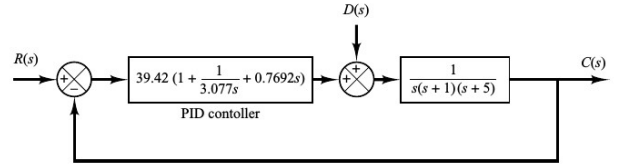

La función de transferencia del sistema viene dada por:


$$\frac{C\left(s\right)}{R\left(s\right)}=G\left(s\right)=\frac{\textrm{Gc}\left(s\right)\textrm{Gp}\left(s\right)}{1+\textrm{Gc}\left(s\right)\textrm{Gp}\left(s\right)}$$


En este caso:


$$\textrm{Gc}\left(s\right)=39\ldotp 42\left(1+\frac{1}{3\ldotp 077s}+0\ldotp 7692s\right)=\frac{30\ldotp 32s^2 +39\ldotp 42s+12\ldotp 81}{s}$$



$$\textrm{Gp}\left(s\right)=\frac{1}{s\left(s+1\right)\left(s+5\right)}=\frac{1}{s^3 +6s^2 +5s}$$


Gc = tf([30.32 39.42 12.81],[1 0]);
Gp = tf([0 1],[1 6 5 0]);
G1 = Gc*Gp/(1+Gc*Gp); 
t=0:0.01:20; % Tiempo.
h1 = stepplot(G1) % Respuesta con entrada de referencia escalón unitario.


h1 =

	resppack.timeplot



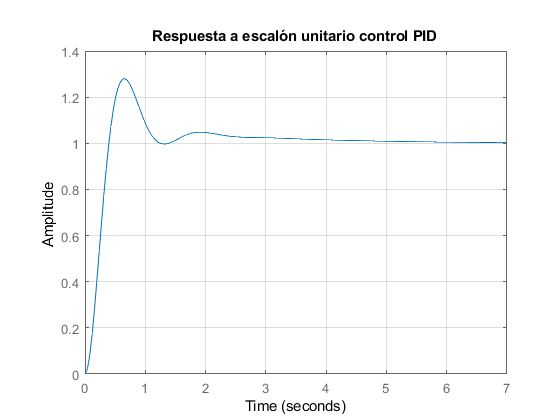

setoptions(h1,'Grid','on');
title('Respuesta a escalón unitario control PID')

En un sistema de control PID básico, si la entrada de referencia es una función escalón, debido a la presencia del término derivativo en la acción de control, la variable manipulada u(t) contendrá una función impulso (una función delta). En un controlador PID real, en lugar del término derivativo puro Tds se emplea. 

                                                                     

donde el parámetro gamma toma un valor alrededor de 0.1. Por tanto, cuando la entrada de referencia es una función escalón, la variable manipulada u(t) no contendrá una función impulso, sino una función en forma de un pulso estrecho. Tal fenómeno se denomina set point kick o patada en el punto de consigna.

## 2)  **Respuesta de un sistema con controlador I-PD a una entrada escalón**

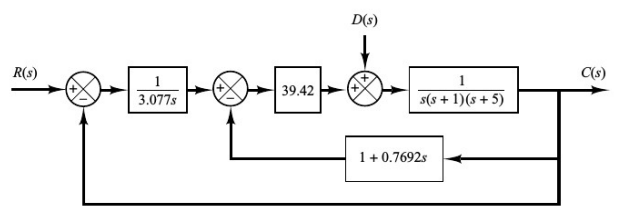

La función de transferencia del sistema viene dada por:


$$\frac{C\left(s\right)}{R\left(s\right)}=G\left(s\right)=\frac{\textrm{GG}\left(s\right)}{1+\textrm{GG}\left(s\right)}$$


Donde:


$$\textrm{GG}\left(s\right)=\frac{\textrm{g1}\left(s\right)\textrm{g2}\left(s\right)\textrm{Gp}\left(s\right)}{1+\textrm{g2}\left(s\right)\textrm{Gp}\left(s\right)\textrm{h1}\left(s\right)}$$



$$\textrm{h1}\left(s\right)=1+0\ldotp 7692s$$



$$\textrm{g2}\left(s\right)=39\ldotp 42$$



$$\textrm{g1}\left(s\right)=\frac{1}{3\ldotp 077s}\;$$


g1 = tf([0 1],[3.077 0]);
g2 = tf([0 39.42],[0 1]);
Gp = tf([0 1],[1 6 5 0]);
h1 = tf([0.7692 1],[0 1]);
GG = g1*(g2*Gp/(1+(g2*Gp*h1))); 
G2 = GG/(1+GG);
h2 = stepplot(G2) % Respuesta con entrada de referencia escalón unitario.


h2 =

	resppack.timeplot



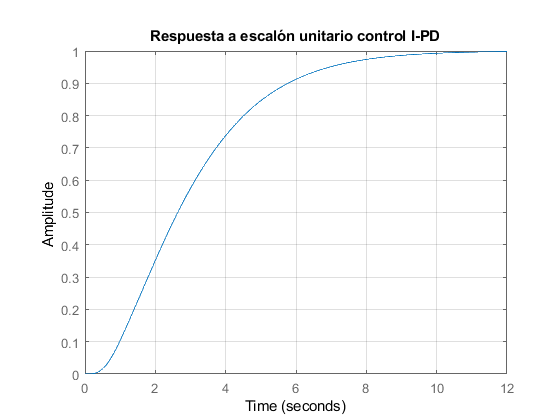

setoptions(h2,'Grid','on');
title('Respuesta a escalón unitario control I-PD')

Para evitar el fenómeno de set point kick, se puede operar la acción derivativa sólo en el camino de realimentación, a fin de que la diferenciación ocurra únicamente en la señal de realimentación y no en la señal de referencia. (PI-D)

En muchas ocasiones, tal cambio escalón en la señal manipulada puede no resultar conveniente. Por tanto, puede convenir mover la acción proporcional y la acción derivativa al camino de realimentación, a fin de que estas acciones sólo afecten a la señal de realimentación. (I-PD)

La entrada de referencia R(s) sólo aparece en la parte de control integral. Por tanto, en el control I-PD es imprescindible tener la acción de control integral para una operación adecuada del sistema de control.